r_1 = 1;
r_2 = 10;
c_1 = 1;
c_2 = 0.1;

First circuit

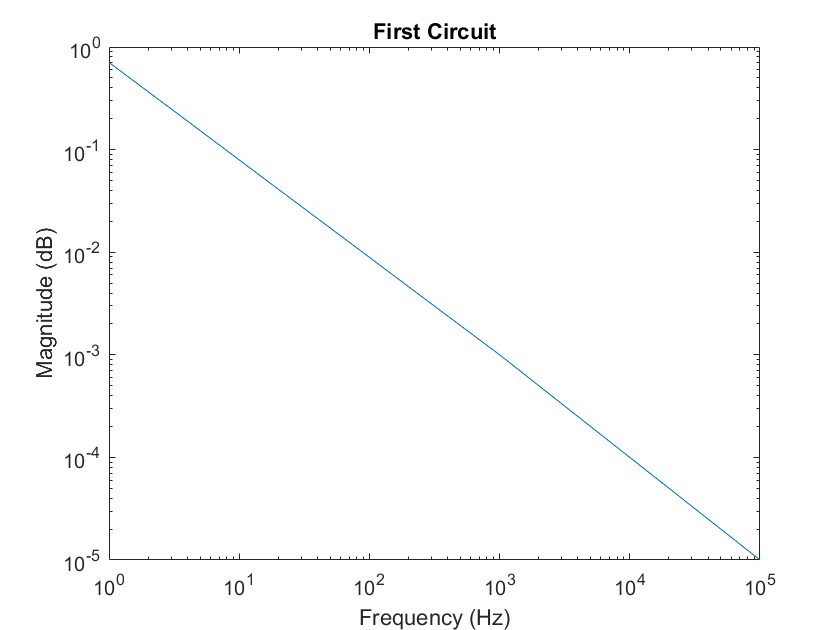

figure
clf
w = linspace(1, 100000);
mag_1 = 1./(1+(1i*w));
loglog(w,abs(mag_1))
title("First Circuit")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")

Second circuit

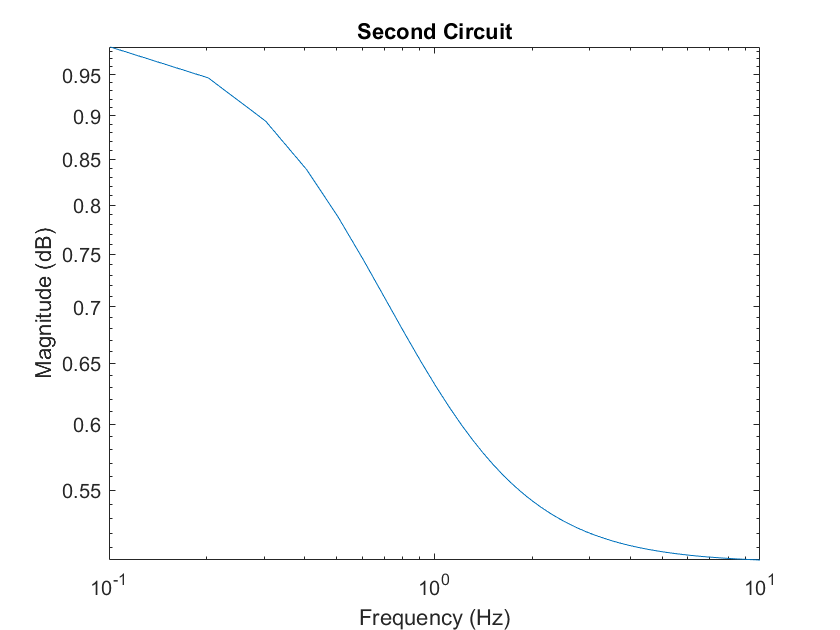

figure
clf
w = linspace(0, 10);
mag_2 = (r_1./(1i.*w.*c_2.*r_2)+1)./((r_1)+(r_1./(1i.*w.*c_2.*r_2)+1));
loglog(w,abs(mag_2))
title("Second Circuit")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")

Third circuit

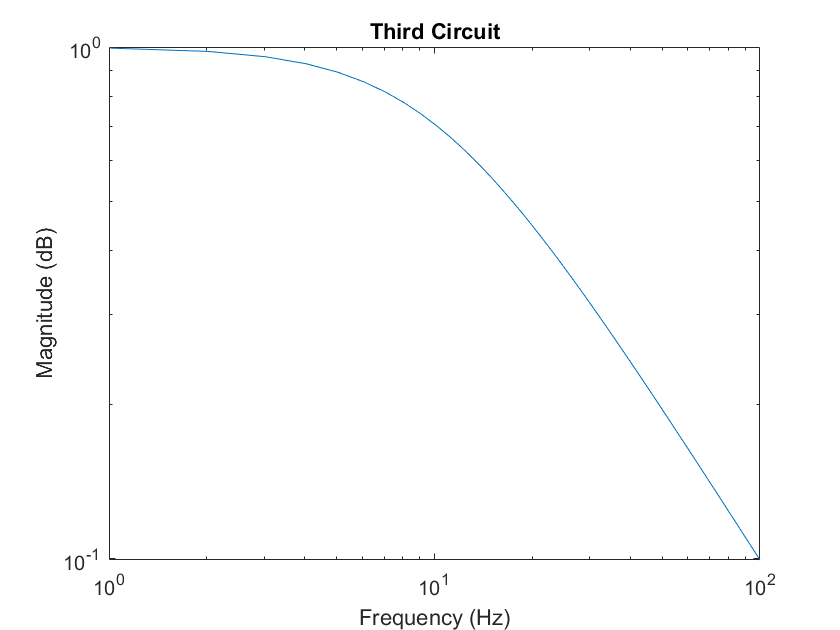

figure
clf
mag_3 = (1i.*r_1.*c_1)./(1+1i.*w.*r_1.*c_1);
w = linspace(0, 100);
loglog(w,abs(mag_3))
title("Third Circuit")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")

Fourth Circuit

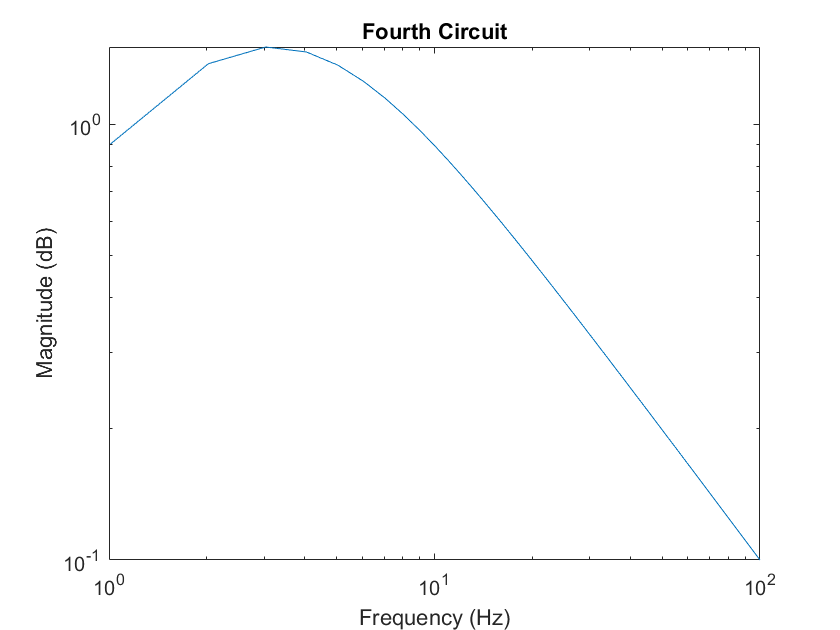

figure
clf
mag_4 = ((r_2))./((r_1 + (1./1i.*w.*c_1) + ((r_2)./(1i.*w.*c_2.*r_2) + 1)));
loglog(w,abs(mag_4))
title("Fourth Circuit")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")

Fifth Circuit

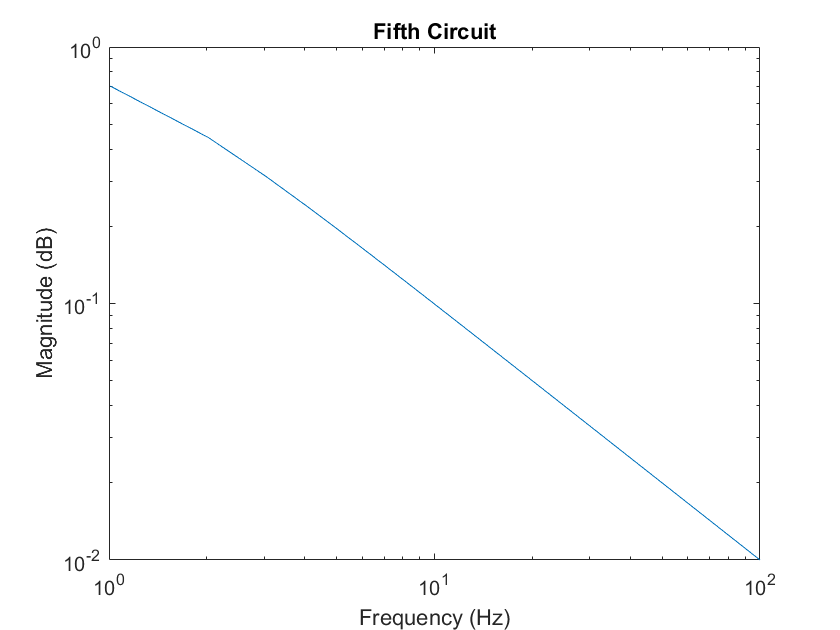

figure
clf
mag_5 = 1./((r_1.*1i.*w.*c_1)+1);
loglog(w,abs(mag_5))
title("Fifth Circuit")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")

Sixth Circuit

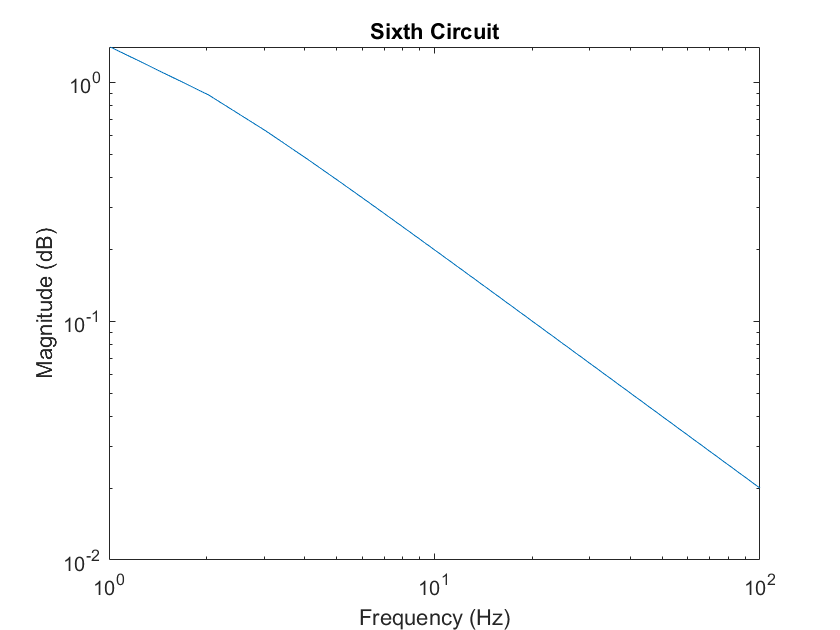

figure
clf
mag_6 = 1./((r_1.*1i.*w.*c_1)+1) + 1./((r_2.*1i.*w.*c_2)+1);
loglog(w,abs(mag_6))
title("Sixth Circuit")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")

Seventh Circuit

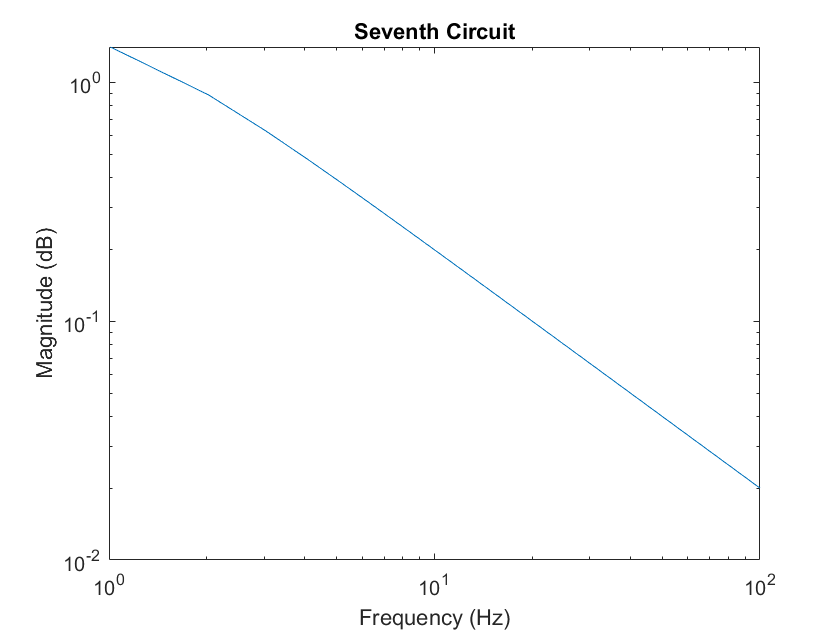

figure
clf
mag_7 = 1./((r_2.*1i.*w.*c_2)+1) + 1./((r_1.*1i.*w.*c_1)+1);
loglog(w,abs(mag_7))
title("Seventh Circuit")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")

Eighth Circuit

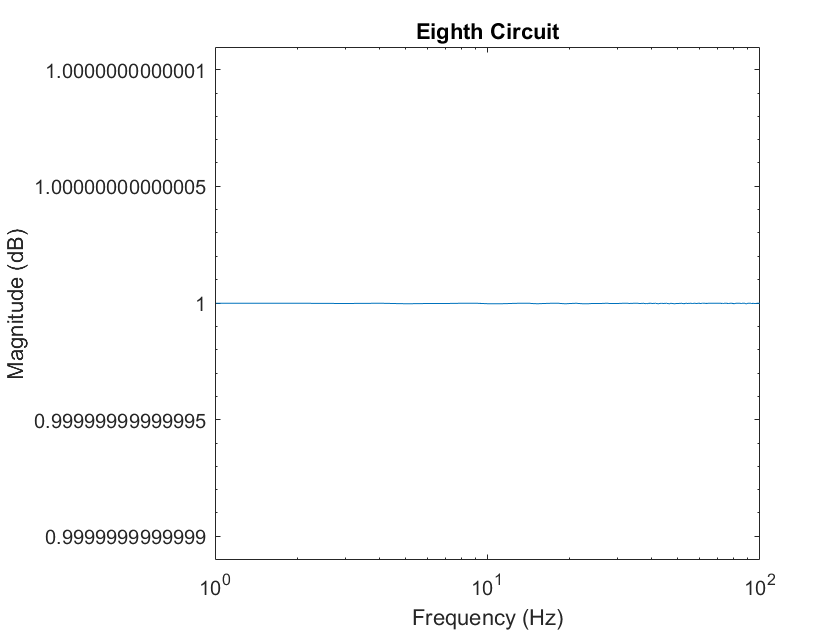

figure
clf
mag_8 = 1./((r_2.*1i.*w.*c_2)+1) + (1i.*w.*c_1)./((r_2.*1i.*w.*c_2)+1);
loglog(w,abs(mag_8))
title("Eighth Circuit")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")

% high pass
r_1 = 2000;
% low pass
r_2 = 30000;
% high pass
c_1 = 1.0E-8;
% low pass
c_2 = 1.0E-9;

% 604 127 = gain 4.75
% total gain = 1070

low_pass = 1/(r_2*c_2);
fprintf('%.0f\n',low_pass)

33333


high_pass = 1/(r_1*c_1);
fprintf('%.0f\n',high_pass)

50000


gain = r_2/r_1

gain = 15


% r_1 = 499; % resistance 1
% r_2 = 301;
% c_1 = 1.0E-8;
% c_2 = 1.0E-8;
% w = 32000; % frequency wnated
w = 40000

w = 40000

%mag_4 = ((r_2))./((r_1 + (1./1i.*w.*c_1) + ((r_2)./(1i.*w.*c_2.*r_2) + 1)))
mag_4 = (-(1./(1+1i.*w.*r_1.*c_1))) * ((1i.*r_1.*c_1)./(1+(1i.*w.*r_1.*c_1))) * (r_2./r_1)

mag_4 = -1.7847e-04 - 4.0155e-05i

abs(mag_4)

ans = 1.8293e-04